# Robotics I Mini-Project 5: Vision Guided Motion

clearvars
cd('C:\Users\kongc\Dropbox\RPI_2021FALL\RoboticsI\FALL21Robotics\MiniProject5')
addpath(genpath('C:\Users\kongc\Dropbox\RPI_2021FALL\RoboticsI\MATLABrelated\'))
addpath(genpath('C:\Users\kongc\Dropbox\RPI_2021FALL\RoboticsI\FALL21Robotics\MiniProject5'))

## Part 1: Camera Model and Projective Geometry

In this part, we want to be able to recreate the image plane pictures of the 3d S-shaped curve using a simple pinhole camera model. 

First we create a pinhole camera object with the given parameters.

cam_def;

The camera object contains 10 intrinsic parameters:

 5 in the skew model $K = \left[ \matrix{f/\rho_w & \alpha f/ \rho_w & u_0 \cr 0 & f/\rho_h & v_0 \cr
0 & 0 & 1}\right]$,

5 in the calculation of true image pixel cordinate $\left[ \matrix{u_{true} \cr v_{true}} \right]$:

$\{k_1, k_2, k_3, k_4, k_5\}$.

Next we load our object "s-shaped path" from the previous project.

load S_sphere_path_uniform.mat pS

We use the origin of the path as $[x_0,y_0,z_0]$ and convert camara origin to the reference frame:

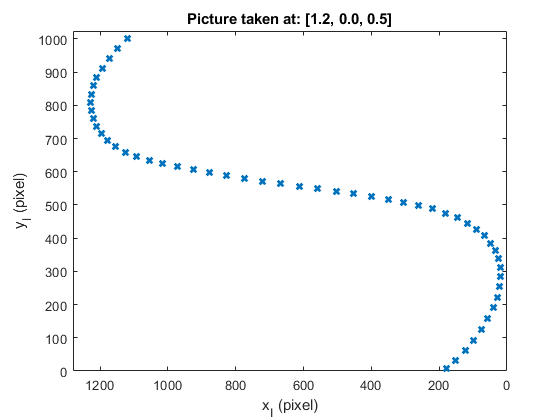

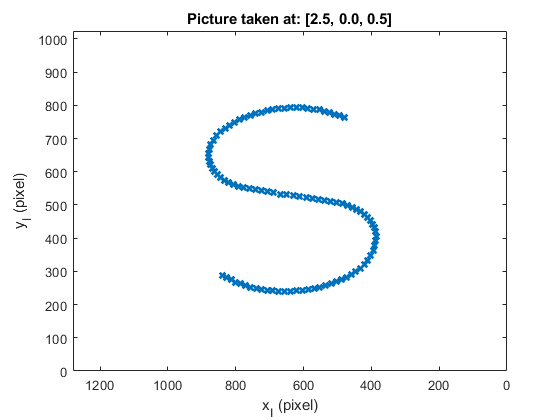

xc = [1.2,2.5];
for i = 1:2
poc = [xc(i);0;0.5];
R0C = [0, 0, -1;
       -1, 0, 0;
       0, 1, 0];
[uv,uvw,P1] = cam_image(cam,[R0C,poc;[0,0,0,1]],pS);
figure;plot(uv(1,:),uv(2,:),'x','LineWidth',2);
xlabel('x_I (pixel)')
ylabel('y_I (pixel)')
title(sprintf('Picture taken at: [%0.1f, %0.1f, %0.1f]',poc(1),poc(2),poc(3)))
axis([0,cam.uv0(1)*2,0,cam.uv0(2)*2])
set(gca,'xdir','reverse')
end

The above plotting method referenced Prof. Wen's Code displayed in Lecture 18.

## Part 2: Intrinsic Camera Parameter Calibration

In previous section, with camera parameter known, we are able to visulize what the camera is seeing with $p_{OC}$ given. In this part, we are given an unknown camera parameter, and the goal is to estimate the intrinsic parameters of the camera with a sets of know target points.

#### a) Derivation of Camera Calibration

First we decided that we will use Moving Camra / Fixed Target appoach.

we first take $M 
$ number of pictures of a known pattern points array. 

We then calculate the 2D homography matrix $H$ that map known points in target frame $(\beta_i)$ to pixels of the image in camera frame $(\alpha_i)$. This require us to reshape $H$ from a 3 by 3 square matrix to a 9 by 1 tall matrix. We can write all the known in $A_i \in \mathbb{R}^{3\times 9}$ where each image would generate a new $A_i, \quad i\in\{1,2,\cdots,M\}$ stacked under the previous one. 

To find an approximate $H \approx \mathcal{N}(A)$, we use $V$ from the smallest singular value of SVD. To extract K from H, we use the idea that rotation matrix has unit norm. This allow us to write out relationship between K and H as $L_mB = 0$ where $B = K^{-1^T}K^{-1} $ . While $H$ is in $L_m$, we use SVD again to approximate $B \approx \mathcal{N}(L_m)$.

Next we use Cholesky Decomposion to solve for $K$.

#### b) how # targets points and number of views affect the estimate

Prof. Wen's target_def generates a square points array with edge length of 0.4. I modified the code a bit so it takes arguments that changes the # targets points inside the square points array. (noise $\sigma = 0.5
$)

**** Singular Values ****: [  6.206,  4.848,  0.3963,  0.0008672,  0.0002096,  2.186e-08  ]
K
   1.0e+03 *

    1.5000         0    0.6400
         0    1.5000    0.5120
         0         0    0.0010

Estimated K
   1.0e+03 *

    1.6082    0.0038    0.6785
         0    1.6098    0.5285
         0         0    0.0010

percentage error in K
 7.2, -, 6
 -, 7.3, 3.2
 -, -, 0



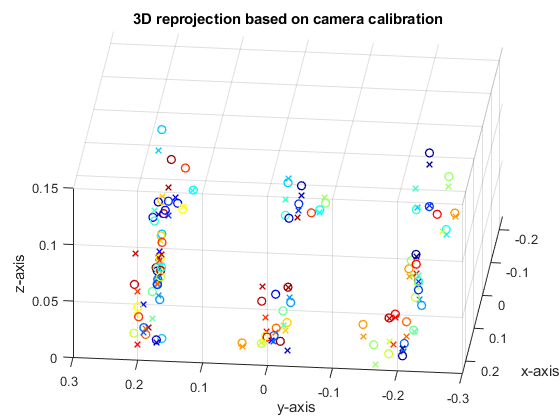

**** Maximum Reprojection Error:    0.925


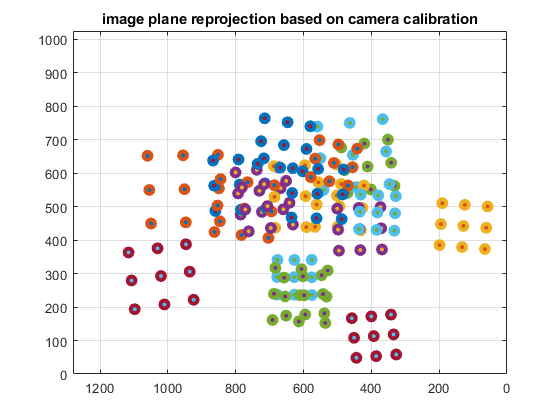

camcalib(20,5)

With 20 images generated and {3,5,7} points generated on the side:

$\%e_K(20,3)=
\left[\matrix{
7.6 &-&1.4 \cr
0&7.8&3.8\cr
-& - & 0
}\right]$, $\%e_K(20,5)=
\left[\matrix{
3 &-&5.6 \cr
0&3.1 &2.7\cr
-& - & 0
}\right]$, $\%e_K(20,9)=
\left[\matrix{
2.2 &-&0.24 \cr
0&2.2&1.1\cr
-& - & 0
}\right]$

It seems that more points slightly improve the percentage error in intrinsic parameter but the increased computation time overshadowed the improvement. 

More points significantly decrease the projection error (about 50% decrease from 3 points to 5 points).

some patterns are out of view
some patterns are out of view
some patterns are out of view
**** Singular Values ****: [  8.758,  6.632,  0.5213,  0.001066,  0.0002381,  2.039e-08  ]
K
   1.0e+03 *

    1.5000         0    0.6400
         0    1.5000    0.5120
         0         0    0.0010

Estimated K
   1.0e+03 *

    1.4972   -0.0020    0.6510
         0    1.4977    0.5057
         0         0    0.0010

percentage error in K
 0.19, -, 1.7
 -, 0.16, 1.2
 -, -, 0



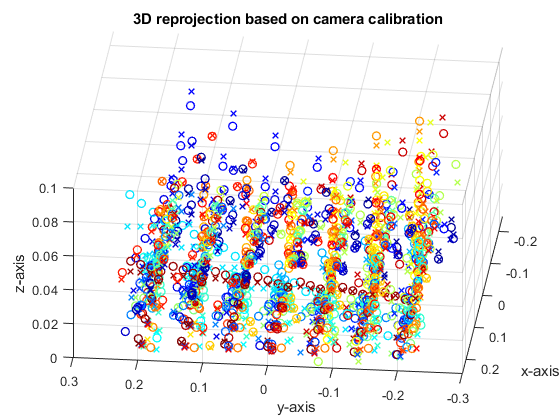

**** Maximum Reprojection Error:    0.56


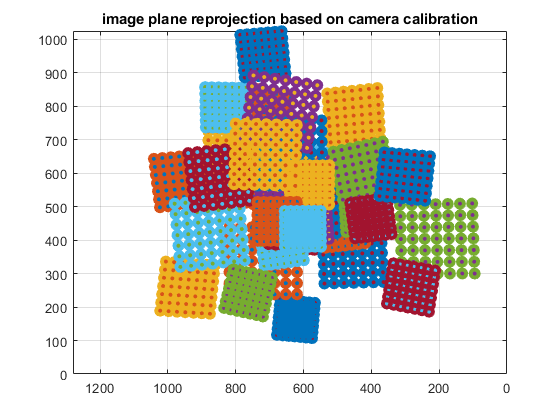

camcalib(40,7)

$\%e_K(3,5)=
\left[\matrix{
28 &-&8.5 \cr
0&28&12\cr
-& - & 0
}\right]$, $\%e_K(20,5)=
\left[\matrix{
3 &-&5.6 \cr
0&3.1 &2.7\cr
-& - & 0
}\right]$, $\%e_K(40,5)=
\left[\matrix{
2.8 &-&1.2 \cr
0&2.7&2.3\cr
-& - & 0
}\right]$

It seems that more images taken improve the overall percentage errors, specifically errors on [$u_0$ $v_0$]. However, it also at the same time increase the projection error.

#### 3) Find #points and #images so that error is with in 1%, reprojection error less than 1 pixel

with Gaussian noise centered at 0, $\sigma = 0.1$

some patterns are out of view
some patterns are out of view
**** Singular Values ****: [  6.389,  4.947,  0.3846,  0.0007043,  0.0001131,  3.176e-09  ]
K
   1.0e+03 *

    1.5000         0    0.6400
         0    1.5000    0.5120
         0         0    0.0010

Estimated K
   1.0e+03 *

    1.4910    0.0004    0.6415
         0    1.4906    0.5140
         0         0    0.0010

percentage error in K
 0.6, -, 0.23
 -, 0.63, 0.38
 -, -, 0



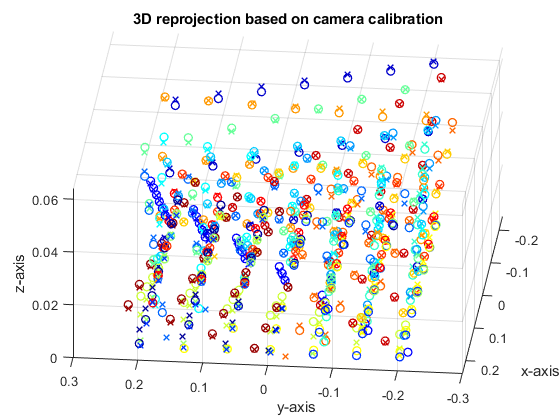

**** Maximum Reprojection Error:    0.149


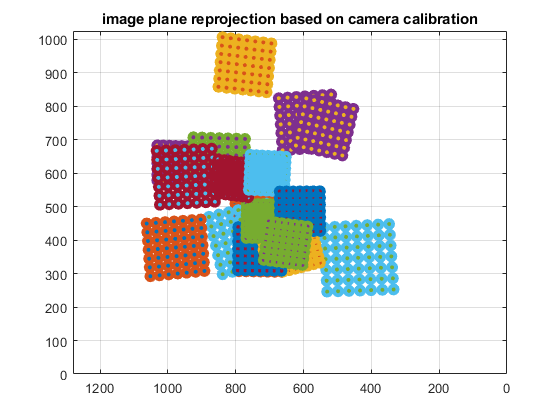

camcalib(20,7)

With 20 pictures and 7 points, the error was within the requirement 9/10 times. 